# Anwendung Kerbsimulation in MAXFAT

Dieses Dokument dient als Erklärung für die verschiedenen Einstellungen die bei der Anwendung der Kerbdehnungssimulation des hier zur Verfügung gestellten Codes getroffen werden können. Für die Kerbsimulation muss ein Objekt der Klasse "Kerbsimulation" erstellt werden. Gezeigt werden:

# 0. Allgemeine Definitionen

Zum schreiben und lesen von Dateien muss jede Rechnung (Job) einen Namen (jobname) und ein Verzeichniss (outpath) besitzen.

jobname = 'Beispiel';
outpath = '00_Temp';
if ~exist(outpath, 'dir')
       mkdir(outpath)
end

# 1 Objektdefinition

Zur Organisation der verschiedenen Funktionen und Optionen zur Ausführung einer Kerbsimulation wurde die Klasse "Kerbsimulation" geschrieben. Zur Defintion einer Instanz der Klasse werden einige Eingaben unbedingt benötig. Andere Werte/Optionen sind auf Standartwerte gesetzt. 

Im Folgenden werden erst alle nötigen Eingaben erklärt. Anschließend werden die wichtigsten Optionen der Klasse Kerbsimulation erklärt. Eine vollständige Liste aller Eigenschaften findet sich in der Datei "Kerbsimulation.m".

Alle nachfolgenden Funktionen müssen nicht selbst aufgerufen werden.

## 1.1 minimale Eingabewerte

### 1.1.1 Lastfolge

Die Lastfolge $L \in \mathbb{R}^{n_k\times n_d}$  , wobei $n_d$ für die Azahl an Daten in der Lastfolge steht und $n_k$ für die Anzahl der angreifenden Lastkanäle. Für die spätere Simulation muss auch noch angegeben werden wieviele Durchläufe durch die Lastfolge simuliert werden sollen.Hier wird Beispielhaft eine Sinuslast erzeugt:

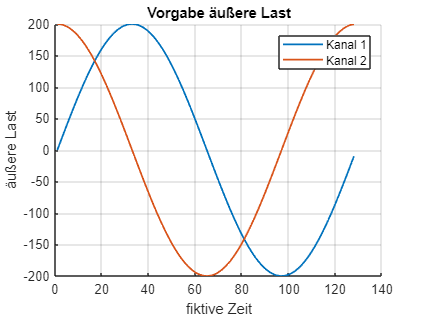

% Beispiellast: Sinus, 2 Lastkanäle 90° Phasenverschoben, mit 128
% Datenpunkte
L = zeros(2,128);
L(1,:) = lastgenerator(1,200,0,1,0,128);  % Kanal 1
L(2,:) = lastgenerator(1,200,90,1,0,128); % Kanal 2

% Anzahl zu simulierender Druchläufe durch die Lastfolge L
ndl = 5;

% ----------------- Beispielplot ----------------------------- %
figLoad = figure; grid on, hold on
plot(L','LineWidth',1.3)
xlabel('fiktive Zeit')
ylabel('äußere Last')
legend('Kanal 1','Kanal 2')
title('Vorgabe äußere Last')

### 1.1.2 Übertragungsfaktoren

Um von der äußeren Last auf die an der Kerbe lokalen elastischen Spannungen zu schließen werden die Übertragungsfaktoren $c_{ij}$ benötigt. 


$${}^e\sigma_{ij} = \sum_{k=1}^{n_k}c_{ij}^kL^k$$


Die Übertragungsfaktoren werden als Matrix $c_{ij} \in \mathbb{R}^{3 \times ,n_k}$  angegeben. Sodass sich die lokalen pseudo-elastischen Spannungen als Matrixmultiplikation ergibt. Für die Definition des lokalen Koordinatensystems wird die lokale $z$ - Achse als Bauteilnormale festgelegt.

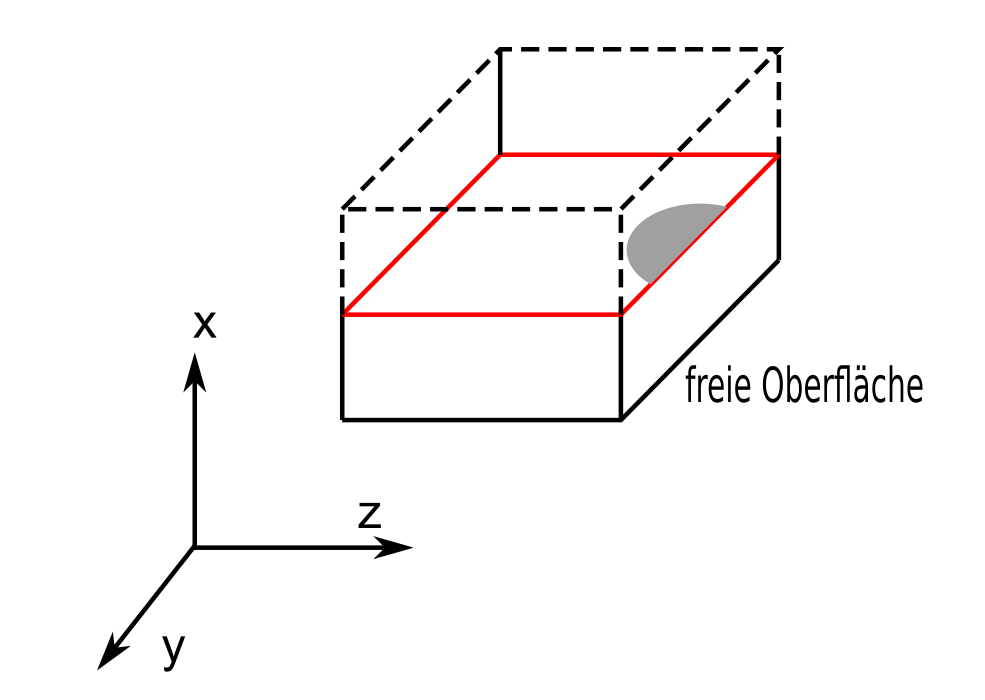

 Die Übertragungsfaktoren sind dann wie folgt geordnet.


$$c_{ij} = \left[\matrix{ c_{xx} & c_{yy} & c_{xy} }\right]^T$$


Die verwendeten Spannungen (und dadurch auch Dehnungen) im gesamten Programm haben damit die folgende Notation.


$$\sigma_{ij} = \left[\matrix{ \sigma_{xx} & \sigma_{yy} & \sigma_{xy} }\right]^T$$



$$\varepsilon_{ij} = \left[\matrix{ \varepsilon_{xx} & \varepsilon_{yy} & \varepsilon_{zz} & \gamma_{xy} }\right]^T$$


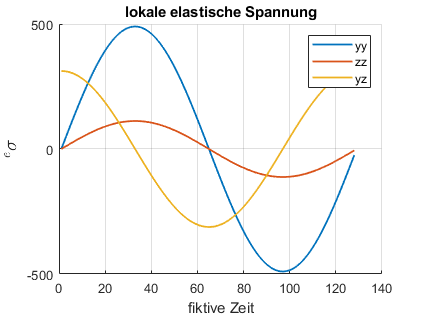

% Beispiel Definition Übertragungsfaktoren
c = [2.45 0.56 0.00;...           % Faktoren Kanal 1
     0.00 0.00 1.56]';            % Faktoren Kanal 2


%  ---- Beispiel bestimmen lokaler Spannungszustände ---------- %
% (wird vom Programm automarisch erledigt)
ESIG = c * L;
figESIG = figure; grid on, hold on 
plot(ESIG','LineWidth',1.3)
xlabel('fiktive Zeit'), ylabel('${}^e\sigma$','Interpreter','latex','FontSize',14);
legend('yy','zz','yz');
title('lokale elastische Spannung')

### 1.1.3 Materialverhalten

Zur Bestimmung der Materialparameter des Plastizitätsmodells müssen einige Materialparameter definiert sein. (Die Parameter für das Plastizitätsmodell können auch per Hand vorgegeben werden, dann würden die hier gemachten Eingaben ungenutzt beleiben)

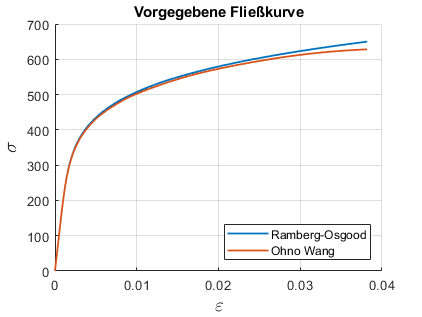

% Statische Kennwerte
E = 206000;  % E-Modul
nu = 0.3;    % Querdehnzahl
Rm = 600;    % Zugfestigkeit

% zyklische Kennwerte
Kstrich = 1115;
nstrich = 0.161;

% ----- Beispiel: Anpassen OhnoWang Modell an Fließkurve ------ %
% (wird später automatisch ausgeführt)

% erzeuge Fließkurve mit Ramberg Osgood
sig = 0:1:650;
epsp = (sig./Kstrich).^(1/nstrich);
eps = sig./E + epsp;
% Bestimme Parameter aus Ramberg Osgood
optpara = 3; % siehe "ro2paraV2.m"
q = 0.01;
ep_M = 0.03;
parameter = ro2paraV2('werkstoff',E,nu,Kstrich,nstrich,10,...
                     'OhnoWang',optpara,q,ep_M);
% integration OhnoWang (zum Darstellen der Fließkurve)
sigOW = solve_matmodel('OhnoWang',1,1,parameter,10,1,eps);

% Vergleichsplot
figFliessKurve = figure; grid on, hold on
plot(eps,sig,'LineWidth',1.3)
plot(eps,sigOW,'LineWidth',1.3)
xlabel('$\varepsilon$','Interpreter','latex','FontSize',14);
ylabel('$\sigma$','Interpreter','latex','FontSize',14);
legend('Ramberg-Osgood','Ohno Wang','Location','southeast')
title('Vorgegebene Fließkurve')

## 1.2 optionale Eingabewerte

Alle folgenden Eingaben können auch weggelassen werden. In diesen Fällen sind folgende Default-Einstellungen getroffen worden (erklärung folgt):

- material             : 'OhnoWang'

- verfahren           : 'PseudoStress Lang'

- eindkerb            : 'Neuber'

- nppara               : 'None'

- M                       : 10

- optpara              : 3

- q                        : 0.01

- ep_M                 : 0.03

- bfk                     : NaN

- Kp                     : NaN

- para                  : automatisch bestimmt

- epara                : automatisch bestimmt

- alpha                : automatisch bestimmt

### 1.2.1 Wahl des Plastizitätsmodells und des Kerbnäherungsverfahrens

Hierzu werden die Variablen ***material*** und ***verfahren*** gesetzt. Dabei ist nicht jedes Materialmodell mit jedem Kerbnäherungsverfahren kompatibel.

material = 'OhnoWang';
verfahren = 'PseudoStress Lang';

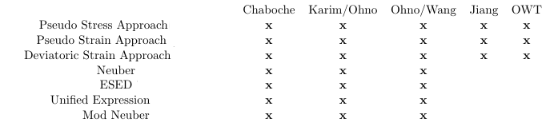

### 1.2.2 Anpassen Plastizitätsmodell an Fließkurven

Die Parameter ***para*** der Plastizitätmodelle (im stabilisierten Zustand) können automatisch an gegebene Fließfunktionen angepasst werden. Sie können auch selbst bestimmt und übergeben werden. Die Genauigkeit dieser Anpassung kann in gewissem Maß gesteuert werden. Dazu stehen die Variablen ***optpara***, ***q***, ***ep_M*** und ***M*** zur verfügung.

Zur Bestimmung der Parameter müssen ***M ***+ 1 Stützpunkte auf der Fließkurve gesetzt werden. ***M ***ist die Anzahl an Backstresstensoren, sie ist auf maximal 20 begrenzt.

***optpara*** = 1,2,3 steht für verschiedene Verfahren wie diese Stützpunkte gesetzt werden können. ***q***, ***ep_M ***sind Steuervariablen der einzelnen Verfahren, siehe "ro2paraV2.m".

Die gleichen Optionen können auch zur Bestimmung der Bauteilfließkurve gesetzt werden, dazu muss vor jeder Option ein "e" angegeben werden. Die Anzahl der Backstresstensoren für das Strukturmodell kann z.B. über die Option ***eM*** gesteuert werden.

% ------ Verschiedene Verfahren zum Bestimmen Parameter Materialmodell -- %
% ( wir automatisch erledigt)

M = 10; % Anzahl der Backstresstensoren

% Verfahren optpara = 1
% ... Äquidistante Stützstellen in Spannungen bis Grenzwert (q)
optpara = 1;
q = 700;
para1 = ro2paraV2('werkstoff',E,nu,Kstrich,nstrich,M,material,optpara,q);

% ... Integration
sig1 = solve_matmodel(material,1,1,para1,M,1,eps);

% ... plot Fließkurve
para1

para1 = 	1.0e+05 *

    2.0600    0.0000    0.0297    0.0125    0.0058    0.0030    0.0016    0.0009    0.0006    0.0003    0.0002    0.0001    0.0001    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0011    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0025


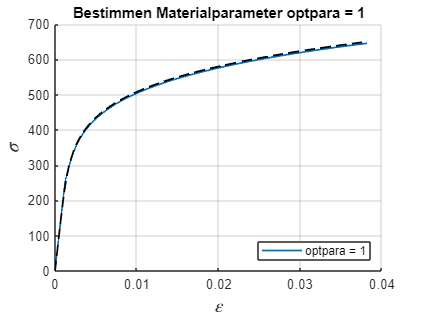

figOptpara1 = figure; grid on, hold on
plot(eps,sig1,'LineWidth',1.3)
plot(eps,sig,'k--','LineWidth',1.3)
xlabel('$\varepsilon$','Interpreter','latex','FontSize',14);
ylabel('$\sigma$','Interpreter','latex','FontSize',14);
legend('optpara = 1','Location','southeast')
title('Bestimmen Materialparameter optpara = 1')

### 1.2.3 Definition der Bauteilfließkurve

Für alle Verfahren aus der Klasse der Strukturfließflächenansätze müssen, zum Bestimmen der Parameter des Strukturmodells ***epara***, Bauteilfließkurven bestimmt werden. Dafür werden die Variablen ***eindkerb***, ***Kp ***und ***bfk ***verwendet. 

***eindkerb ***= 'Neuber'(default), 'ESED', 'NeuberStern','Seeger Heuler', 'Seeger Beste', 'selbst' die Variable zur Auswahl der Kerbnäherung zur Bestimmung der Bauteilfließkurve. Bei der Option 'selbst' muss ***bfk ***gegeben sein. Bei allen Verfahren bei denen die Traglastformzahl benötigt wird, muss ***Kp ***mit angegeben werden.

% ---- Verschiedene Bauteilfließkurven -------------------------------- %
% (wird automatisch erledigt)

Kp = 3;   % Traglastformzahl

% 1. Pseudo Stress Verfahren
verfahren = 'PseudoStress';
% Verschiedene eindkerb PseudoStrain

% ... Neuber Stern
epara = ro2paraV2(verfahren,E,nu,Kstrich,nstrich,M,...
                  material,optpara,q,ep_M,'Neuber Stern',Kp);
[esig_NS,~] = uniax_neuberstern(E,sig,epsp,Kstrich,nstrich,Kp);
sig_NS = solve_matmodel(material,1,1,epara,M,1,eps);


% aus selbst gesetzter Bauteilfließkurve (Hier einfach die SeegerBeste genommen)
[esig_SB,~] = uniax_seegerbeste(E,sig,epsp,Kstrich,nstrich,Kp);
bfk = [esig_SB;epsp]';
epara = bfk2paraV2(verfahren,bfk,M,material,E,nu,optpara,1350);
sig_bfk = solve_matmodel(material,1,1,epara,M,1,eps);

% Plot
figBFK = figure; grid on, hold on
plot(epsp+esig_NS/E,esig_NS,'LineStyle',"-",'LineWidth',1.2,"Color",'k')
plot(eps,sig_NS,'LineWidth',1.2,'HandleVisibility',"off")
plot(epsp+esig_SB/E,esig_SB,'LineStyle',"--",'LineWidth',1.2,"Color",'k')
plot(eps,sig_bfk,'LineStyle',"-.",'LineWidth',1.2,'HandleVisibility',"off")
legend('Neuber Stern','Seeger Beste',"Location","best")
xlabel('EPS'),ylabel('ESIG'),title('BFK Pseudo Stress')


### 1.2.4 Nichtproportionale Verfestigung

Zum Berücksichtigen der Nichtproportionalen Verfestigung wird hier der Ansatz nach Marquis und Socie verwendet, $K^\prime_{np} = \left(1+\alpha f_{np}\right)K^\prime$. Dazu muss der Parameter $f_{np}$ zum Berechnen der Nichtproportionalität angegeben werden. Dazu wir die Option ***nppara ***verwendet. Der Materialparameter ***alpha ***wird, falls nicht angegeben aus der Zugfestigkeit abgeschätzt.

# 2 Ausführen der Kerbsimulation

## 2.1 Erzeugen von Kerbsimulation Instanz

Zum erzeugen einer Instanz der Klasse Kerbsimulation muss zunächst der minimale Input übergeben werden. Um eine Option zu setzen, muss zuerst der Variablen Name als String und anschließend der Wert der Variable übergeben werden.

% Beispiel mehrere Definitionen
K = Kerbsimulation(jobname,outpath,...
                    L,c,ndl,Rm,E,nu,Kstrich,nstrich,...
                    'material','Chaboche',...              % Materialmodell umstellen
                    'verfahren','PseudoStrain',...         % Kerbnäherungsverfahren umstellen
                    'eindkerb','Seeger Beste',...          % Bestimmen der Bauteilfließkurve umstellen
                    'Kp',Kp,...                            % Traglastformzahl angeben
                    'nppara','Riess');                     % Nichtproportionale Verfestigung berücksichtigen


Bei der Definition einer Instanz der Klasse Kerbsimulation werden einige Daten automatisch erzeugt. So wird für die pseudo elastische Lastfolge eine Datei mit dem Namen "outpath/jobname.pth" erzeugt. Ein Verweis auf die Datei ist in der Eigenschaft K.esigpath gespeichert.

fprintf('Lastdatei         : %s\n',K.esigpath)
fprintf('Anzahl Durchläufe : %i\n',K.ndl)
fprintf('Anzahl Lastkanäle : %i\n',K.nkana)
fprintf('Anzahl Datenpunkte: %i\n',K.ndata)

Die Datei ist als binary file Datei gespeichert. In ihr stehen $\left[\text{DLZ},{}^e\sigma\right]^T$ als Double Werte.

Die Varialbe ***DLZ ***(***D***urch***L***auf***Z***ähler) dient als fikitve Zeit. Die gegebne Lastfolge ***L*** definiert einen Durchlauf, sie geht vom Zeitpunkt ***DLZ = 0 ***bis ***DLZ = 1***. Bei der Kerbsimulation werden dann ***ndl*** Durchläufe  berechnet. (Die Variable ***DLZ ***dient später als Lebensdauer, es werden immer Teildurchläufe angegeben.)

% Einlesen elastische Spannungen aus Beispiel 
fid = fopen(K.esigpath,'r'); DATA = fread(fid,[4,Inf],'double'); fclose(fid);
% Auslesen Daten
DLZ = DATA(1,:);
ESIG = DATA(2:4,:);
% Beispiel Plot
figESIG = figure; grid on, hold on
plot(DLZ,ESIG','LineWidth',1.2)
xlabel('DLZ'),ylabel('ESIG');
legend('xx','yy','xy')

Um zwischen zwei Durchläufen oder beim Start der Lastfolge keine numerischen Ungenaugkeiten (z.B durch zu große Inkremente) bei der Integration der Materialmodelle auftreten, werden automatisch Anfahrt- und Zwischenwerte eingefügt. 

% Anfahrtweg
figureAnfahrt = figure; grid on, hold on
idx = DLZ < 0.3;
plot(DLZ(idx),ESIG(:,idx)','LineWidth',1.2);
title('Anfahrt Weg, Last startet nicht in 0')
% Zwischen Weg
figureZW = figure; grid on, hold on
idx = DLZ < 1.2 & DLZ > 0.9;
plot(DLZ(idx),ESIG(:,idx),'LineWidth',1.2);
title('Zwischen Weg, zwischen zwei Durchläufen')

## 2.2 ausführen Kerbsimulation

Um eine Kerbsimulation auszuführen, muss die Funktion "kerbsimulation" aufgerufen werden. Das Ergebniss wird in die Datei "outpath/jobname.sig" in der Reihenfolge $\left[\text{DLZ},\sigma,\varepsilon\right]^T$ geschrieben.

% Ausführen mit default Einstellungen
% - Pseuod Stress
% - BFK Neuber
% - Ohno Wang Modell
tic
sigepsfile = K.kerbsimulation();
fprintf('Dauer Kerbsimulation: %.3f Sekunden\n',toc)

% Lese Ergebnisse
[SIG,EPS,DLZ] = read_sigepsfile(sigepsfile,3,2);

% Plote Ergebnisse
figKS = figure; grid on, hold on
plot(EPS([1 2 4],:)',SIG')
xlabel('EPS'), ylabel('SIG'),legend('xx','yy','xy'), title('Ergebnisse Kerbsimulation')

# 3. Beispiele

## 3.0 Beispiel 0, Minimalbeispiel

Kerbdehnungssimulation mit default Einstellungen. 

% Objektdefinition
K_0 = Kerbsimulation('Beispiel0',outpath,...                % Standarteingaben
                    L,c,ndl,Rm,E,nu,Kstrich,nstrich);
% Ausführen Kerbsimulation
sigepsfile = K_0.kerbsimulation();

% plote Ergebnisse
[SIG_0,EPS_0,DLZ_0] = read_sigepsfile(sigepsfile,3,2);
figKS = figure; grid on, hold on
plot(EPS_0([1 2 4],:)',SIG_0','LineWidth',1.2)
xlabel('EPS'), ylabel('SIG'),legend('xx','yy','xy','Location','southeast')
title('Ergebnisse Kerbsimulation Beispiel 0')

## 3.1 Beispiel 1, Kerbsimulation mit Zusatzeinstellungen

- Pseudo Strain Approach

- Karim Ohno Modell

- mit NP Korrektur

- BFK aus Seeger Beste

- unterschiedliche Anzahl Backstresstensoren für Material- & Strukturmodell

% Definiere Kerbsimulation
K_1 = Kerbsimulation('Beispiel1',outpath,...                % Standarteingaben
                    L,c,ndl,Rm,E,nu,Kstrich,nstrich,... %         "
                    'verfahren','PseudoStrain',...      % Kerbsimulationsverfahren
                    'eindkerb', 'Seeger Beste',...      % Bauteilfließkurve
                    'Kp',3,...                          % Traglastformzahl
                    'nppara','Gaier',...                % fnp
                    'alpha',0.25,...                    % Materialparameter
                    'material','KarimOhno',...          % Materialmodell
                    'M', 10,...                         % Anzahl Backstresstensoren Material
                    'eM',15 ...                         % Anzahl Backstresstensoren Strukturmodell
                     );
% Ausführen
sigepsfile = K_1.kerbsimulation();

% plote Ergebnisse
[SIG_1,EPS_1,DLZ_1] = read_sigepsfile(sigepsfile,3,2);
figKS = figure; grid on, hold on
plot(EPS_1([1 2 4],:)',SIG_1','LineWidth',1.2)
xlabel('EPS'), ylabel('SIG'),legend('xx','yy','xy','Location','southeast')
title('Ergebnisse Kerbsimulation Beispiel 1')

## 3.2 Beispiel 2, Kerbsimulation mit Zusatzeinstellungen 2

- Kerbsimulation mit Unified Expression

- Chaboche Modell

- Materialparameter bestimmt mit Stützstellen in Spannungen

% Definiere Kerbsimulation
K_2 = Kerbsimulation('Beispiel2',outpath,...                % Standarteingaben
                    L,c,ndl,Rm,E,nu,Kstrich,nstrich,... %         "
                    'verfahren','UniExp',...            % Kerbsimulationsverfahren
                    'Cq',0.2,...                        % Parameter Unified Expression
                    'material','KarimOhno',...          % Materialmodell
                    'M', 10,...                         % Anzahl Backstresstensoren Material
                    'optpara',1,...                     % Bestimme Materialparameter
                    'q',Rm...                           %         "
                    );
% Ausführen
sigepsfile = K_2.kerbsimulation();

% plote Ergebnisse
[SIG_2,EPS_2,DLZ_2] = read_sigepsfile(sigepsfile,3,2);
figKS2 = figure; grid on, hold on
plot(EPS_2([1 2 4],:)',SIG_2','LineWidth',1.2)
xlabel('EPS'), ylabel('SIG'),legend('xx','yy','xy','Location','southeast')
title('Ergebnisse Kerbsimulation Beispiel 2')

## 3.3 Beispiel 3 "Eigendehnungen"

Starte Kerbsimulation mit selbstgesetzten Zustandsvariablen. 

Bsp. plastische Dehnungen im PseuoStress Ansatz als "Eigendehnungen":

% Eigendehnung
EPS_EIG = [0.005 -0.001 0.006]';
SIG_EIG = [50 0 70]';
DEL = elast_nachgiebigkeit(E,nu,3,2);

% Kerbsimulation
K_3 = Kerbsimulation('Beispiel3',outpath,...                % Standarteingaben
                    L,c,200,Rm,E,nu,Kstrich,nstrich);
% Umstellen Zustandsvariablen Plastizitätsmodell
K_3.ZVAR(4:6) = EPS_EIG;
K_3.EZVAR(1:3) = EPS_EIG + DEL * SIG_EIG; 
K_3.EZVAR(4:6) = EPS_EIG;

% Kerbsimulation
sigepsfile = K_3.kerbsimulation(K_3.ZVAR,K_3.EZVAR);

% plote Ergebnisse                     
[SIG3,EPS3,DLZ3] = read_sigepsfile(sigepsfile,3,2);                      
figBS3 = figure; grid on, hold on
plot(EPS3([1 2 4],:)',SIG3')
xlabel('EPS'), ylabel('SIG'),legend('xx','yy','xy','Location','southeast')
title('Ergebnisse Kerbsimulation Beispiel 3')